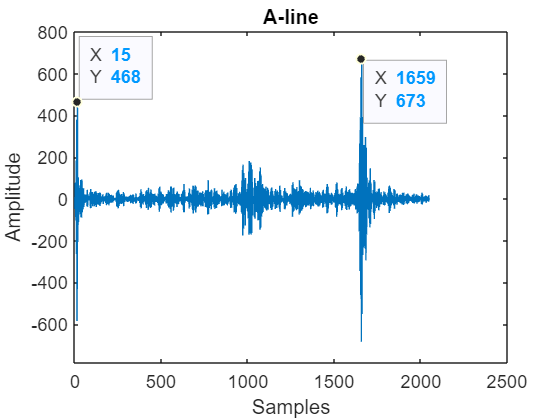

%OPEN THE DATA
load("phantom_raw_data.mat");
data = rf_bbf(:,64,64);
plot(data);
title("A-line");
xlabel('Samples');ylabel('Amplitude');

%calculation
fs = 20*(10^6); %Hz
n = size(rf_bbf);
%transmit time
[pks,locs] = findpeaks(data);
[sorted_pks,sorted_idx] = sort(pks,'descend');
sorted_locs = locs(sorted_idx);
[pks1,locs1] = findpeaks(data(1:100));
[sorted_pks1,sorted_idx] = sort(pks1,'descend');
sorted_locs1 = locs1(sorted_idx);
n1 = sorted_locs(1);
n2 = sorted_locs1(1);
A1 = sorted_pks(1);
A2 = sorted_pks1(1);
transmit_time = (1/fs)*(n1-n2);
%phantom paramters
dim = [0.08,0.05,0.05];
mass = 0.209;
%speed
speed = 2*dim(3)/transmit_time;
%time of flight
t1 = n1/fs;
t2 = n2/fs;
%depth
d1 = speed*t1/2;
d2 = speed*t2/2;
%attenuation factor
ua = -(1/(d1-d2))*log(A2/A1);
%attenuation coefficient
a = 8.7 * ua;
%density
den = mass/(dim(1)*dim(2)*dim(3));
%accoustic impedance
Z = den * speed;
rintf('Sampling frequency = %.0f Hz\n', fs);

Sampling frequency = 20000000 Hz


fprintf('Sampling time = %.8f s\n', 1/fs);

Sampling time = 0.00000005 s



fprintf('No. of Samples = %d\n', n(1));

No. of Samples = 2048


fprintf('Transmit time = %.8f s\n', transmit_time);

Transmit time = 0.00008220 s


fprintf('Speed = %.4f m/s\n', speed);

Speed = 1216.5450 m/s


fprintf('Attenuation factor = %.4f\n', ua);

Attenuation factor = 7.2655


fprintf('Attenuation coefficient = %.4f\n', a);

Attenuation coefficient = 63.2102


fprintf('Density of Phantom = %d kg/m3\n', den);

Density of Phantom = 1045 kg/m3


fprintf('Acoustic Impedance = %.0f Pa-s/m3\n', Z);

Acoustic Impedance = 1271290 Pa-s/m3
